%Anshuman and Aly

clc;
clear;
close all;

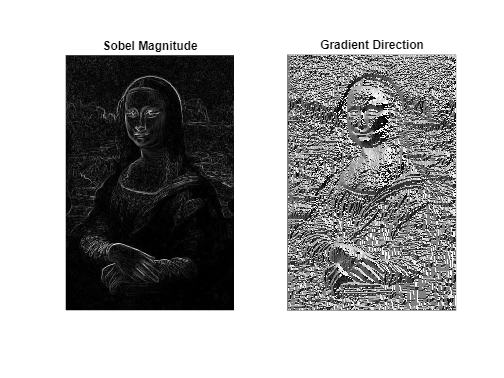

%Mona Lisa
% Read and convert image to grayscale
image = imread("mona lisa.png");
grayImage = double(rgb2gray(image));
% Define Sobel kernels
sobelX = [-1 0 1; -2 0 2; -1 0 1];
sobelY = [-1 -2 -1; 0 0 0; 1 2 1];

% Apply Sobel filter using convolution
[rows, cols] = size(grayImage);
gradientX = zeros(rows, cols);
gradientY = zeros(rows, cols);

% Convolve
for i = 2:rows-1
    for j = 2:cols-1
        region = grayImage(i-1:i+1, j-1:j+1);
        gradientX(i, j) = sum(sum(region .* sobelX));
        gradientY(i, j) = sum(sum(region .* sobelY));
    end
end

% Compute magnitude and gradient direction
magnitude = sqrt(gradientX.^2 + gradientY.^2);
gradientDirection = atan2(gradientY, gradientX);

% Plots
figure;
subplot(1, 2, 1), imshow(magnitude, []), title('Sobel Magnitude');
subplot(1, 2, 2), imshow(gradientDirection, []), title('Gradient Direction');

%2nd Problem

% Gradient products
Ix2 = gradientX.^2;
Iy2 = gradientY.^2;
Ixy = gradientX .* gradientY;

% Gaussian kernel (3x3)
gaussianKernel = [1 2 1; 2 4 2; 1 2 1] / 16;

% Smooth gradient products using conv
Ix2_smoothed = conv2(Ix2, gaussianKernel, 'same');
Iy2_smoothed = conv2(Iy2, gaussianKernel, 'same');
Ixy_smoothed = conv2(Ixy, gaussianKernel, 'same');

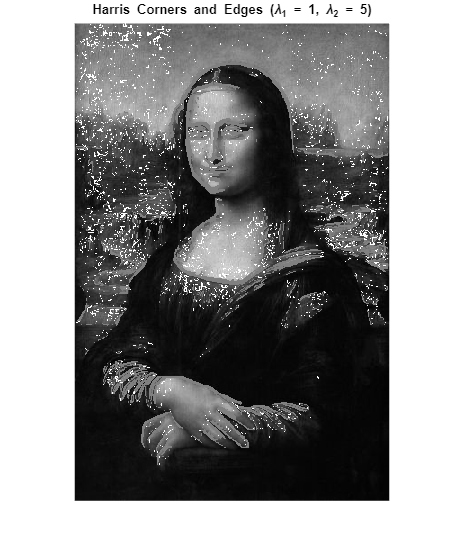

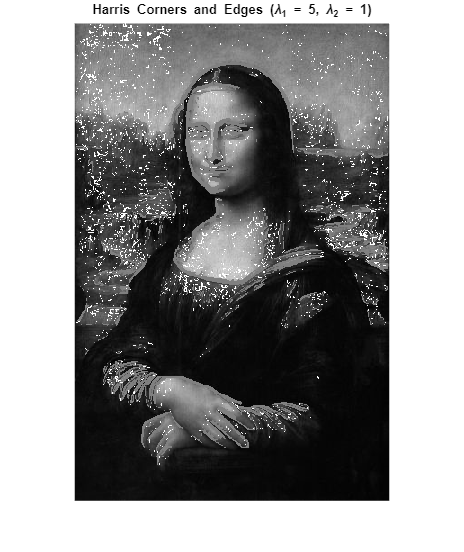

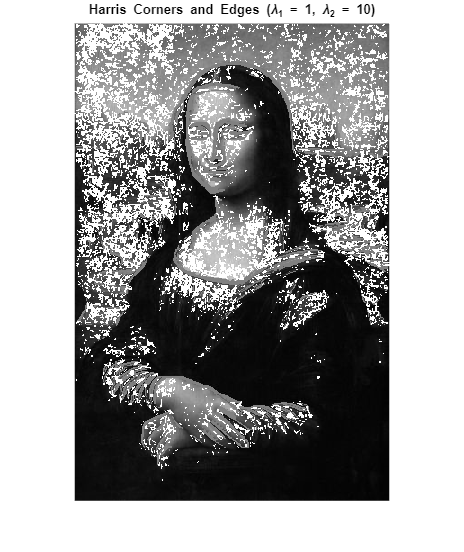

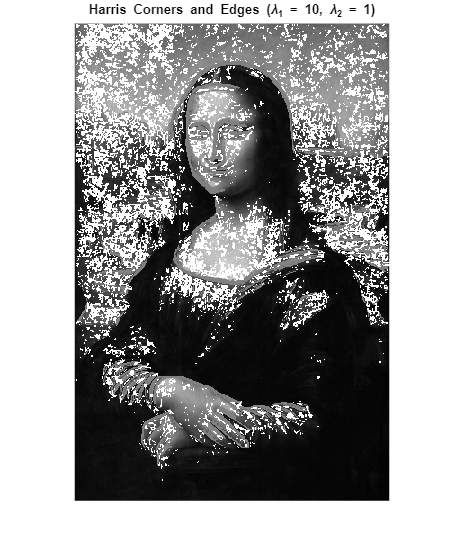

lambdaRatios = {[1, 5], [5, 1], [1, 10], [10, 1]};
threshold = 1e5;

% Initialize a marked image with the original grayscale image
markedImage = grayImage;

% Threshold for edges based on gradient magnitude
edgeThreshold = 1e2; % Adjust as needed
edges = magnitude > edgeThreshold;

% Mark edges with 128
markedImage(edges) = 128;

for k = 1:length(lambdaRatios)
    lambda1 = lambdaRatios{k}(1);
    lambda2 = lambdaRatios{k}(2);

    % Compute R = det(M) - k * trace(M)^2
    detM = Ix2_smoothed .* Iy2_smoothed - Ixy_smoothed.^2;
    traceM = Ix2_smoothed + Iy2_smoothed;
    R = detM - (lambda1 / lambda2) * (traceM.^2);

    % Threshold R
    corners = R > threshold;

    grayImage = cast(grayImage, "uint8");
    %imshow(grayImage)

    % Mark corners with 255
    markedImage(corners) = 255;

    % Display results
    figure;
    imshow(markedImage, []); % Show the image with marked corners and edges
    title(['Harris Corners and Edges (\lambda_1 = ', num2str(lambda1), ...
           ', \lambda_2 = ', num2str(lambda2), ')']);
end

Part a is more sensitive and will classify more  regions as flat.

Part b reduces the number of flat regions, more strict.

Part a detects fewer corners because some regions are not classified as corners

Part b more likely to detect corners especially with regions of larger intensity variations.

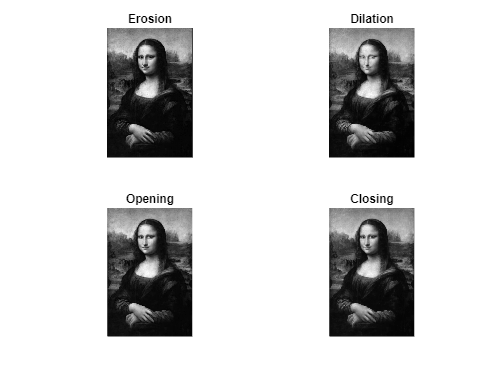

%3rd Problem
se = ones(3, 3);

% Padding
paddedImage = uint8(paddedImage);
% Initialize outputs
[rows, cols] = size(GIs);
erodedImage = zeros(rows, cols);
dilatedImage = zeros(rows, cols);

% Erosion
for i = 2:rows+1
    for j = 2:cols+1
        region = paddedImage(i-1:i+1, j-1:j+1);
        erodedImage(i-1, j-1) = min(region(se == 1)); % Minimum in the neighborhood
    end
end

% Dilation
for i = 2:rows+1
    for j = 2:cols+1
        region = paddedImage(i-1:i+1, j-1:j+1);
        dilatedImage(i-1, j-1) = max(region(se == 1)); % Max in neighborhood
    end
end

% Opening
openedImage = zeros(rows, cols);
tempImage = padarray(erodedImage, [1, 1]);
for i = 2:rows+1
    for j = 2:cols+1
        region = tempImage(i-1:i+1, j-1:j+1);
        openedImage(i-1, j-1) = max(region(se == 1));
    end
end

% Closing
closedImage = zeros(rows, cols);
tempImage = padarray(dilatedImage, [1, 1]);
for i = 2:rows+1
    for j = 2:cols+1
        region = tempImage(i-1:i+1, j-1:j+1);
        closedImage(i-1, j-1) = min(region(se == 1));
    end
end

% Display results
figure;
subplot(2, 2, 1), imshow(erodedImage, []), title('Erosion');
subplot(2, 2, 2), imshow(dilatedImage, []), title('Dilation');
subplot(2, 2, 3), imshow(openedImage, []), title('Opening');
subplot(2, 2, 4), imshow(closedImage, []), title('Closing');

function grayImage = rgbToGrayscale(imagePath)

    % Read the RGB image
    rgbImage = imread(imagePath);

    rgbImage = double(rgbImage);

    % Extract RGB channels
    R = rgbImage(:, :, 1); % R
    G = rgbImage(:, :, 2); % G
    B = rgbImage(:, :, 3); % B

    % Apply the luminosity equation
    grayImage = 0.2126 * R + 0.7152 * G + 0.0722 * B;

    % Display the resulting grayscale image
    figure;
    imshow(grayImage, []);
    title('Grayscale Image (Luminosity Method)');
end
